%  %Opening the files.
%  fileID = fopen('10kHz.txt', 'r');
%  fileID2 = fopen('125kHz.txt', 'r');
%  fileID3 = fopen('250kHz.txt', 'r');
%  %Reading the data stored in them! 
%  data1 = fscanf(fileID, '# KERNEL: Time= %f, Counter= %d, DDS_Sin= %d', [3, Inf]);
%  data2 = fscanf(fileID2, '# KERNEL: Time= %f, Counter= %d, DDS_Sin= %d\n', [3, Inf]);
%  data3 = fscanf(fileID3, '# KERNEL: Time= %f, Counter= %d, DDS_Sin= %d\n', [3, Inf]);
%  % Closing all the files
%  fclose(fileID);fclose(fileID2);fclose(fileID3);
% 
%  % Extracting the N (counter), amp and the subsequent time values!
% time1 = data1(1, :);
% counter1 = data1(2, :);
% DDS_SIN1 = data1(3, :);
% 
% time2 = data2(1, :);
% counter2 = data2(2, :);
% DDS2 = data2(3, :);
% 
% time3 = data3(1, :);
% counter3 = data3(2, :);
% DDS3 = data3(3, :);
% 
% % Plot the graphs
% figure;
% subplot(3, 1, 1);
% plot(time1, DDS_SIN1, '--r', 'LineWidth', 1, 'Color', [1, 0, 0, 0.5]);
% hold on;
% stairs(time1, DDS_SIN1, 'k', 'LineWidth', 1);
% hold off;
% legend('Analog', 'Digital');
% xlabel('Time');
% ylabel('Sine');
% title('10 kHz Sine Wave Generated Using', 'DIRECT DIGITAL SYNTHESIZER');
% grid on;
% 
% subplot(3, 1, 2);
% plot(time2, DDS2, '--r', 'LineWidth', 1, 'Color', [1, 0, 0, 0.5]);
% hold on;
% stairs(time2, DDS2, 'k', 'LineWidth', 1);
% hold off;
% legend('Analog', 'Digital');
% xlabel('Time');
% ylabel('Sine');
% title('125-kHz Sine Wave Generated');
% grid on;
% 
% subplot(3, 1, 3);
% plot(time3, DDS3, '--r', 'LineWidth', 1, 'Color', [1, 0, 0, 0.5]);
% hold on;
% stairs(time3, DDS3, 'k', 'LineWidth', 1);
% hold off;
% legend('Analog', 'Digital');
% xlabel('Time');
% ylabel('Sine');
% title('250 kHz Sine Wave Generated');
% grid on;


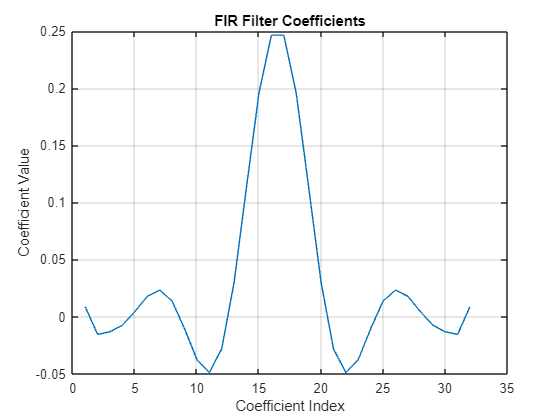

load("FilterCoefficients.mat","DSD2");
coefficients = DSD2;
plot(coefficients);
title('FIR Filter Coefficients');
xlabel('Coefficient Index');
ylabel('Coefficient Value');
grid on;

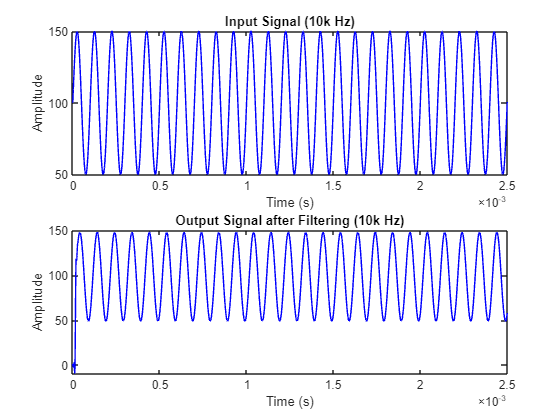


% Time vector
Fs = 1000000; % Sampling frequency (Hz)
%t = 0:1/Fs:1-1/Fs; % Time vector for 1 second
t = linspace(0,1,Fs);

% Generate input signals
f1 = 10000; % Frequency of the first sine signal (Hz)
f2 = 200000; % Frequency of the second sine signal (Hz)
x1 = 50*sin(2*pi*f1*t) + 100; % 10k Hz sine wave
x2 = 50*sin(2*pi*f2*t) + 100; % 200000 Hz sine wave

% Apply the FIR filter to the input signals
y1 = filter(coefficients, 1, x1);
y2 = filter(coefficients, 1, x2);

% Plot the input and output signals for 100 Hz
figure;
subplot(2,1,1);
plot(t, x1, 'b');
title('Input Signal (10k Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.0025]);


subplot(2,1,2);
plot(t, y1, 'b');
title('Output Signal after Filtering (10k Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.0025]);

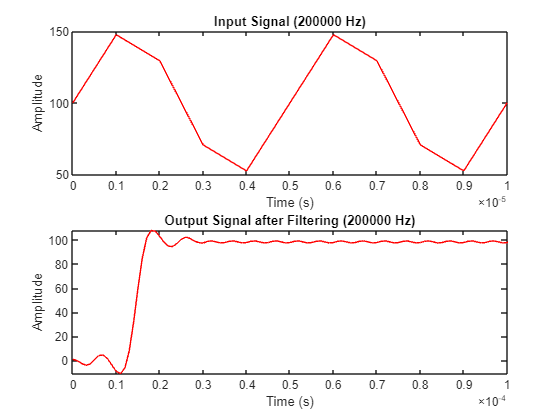


% Plot the input and output signals for 200000 Hz
figure;
subplot(2,1,1);
plot(t, x2, 'r');
title('Input Signal (200000 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.00001]);

subplot(2,1,2);
plot(t, y2, 'r');
title('Output Signal after Filtering (200000 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.0001]);

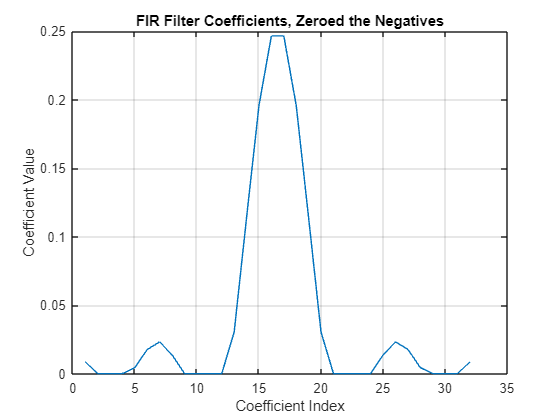

clf;

% Set negative coefficients to zero
c = coefficients;
coefficients(coefficients < 0) = 0;

plot(coefficients);
title('FIR Filter Coefficients, Zeroed the Negatives');
xlabel('Coefficient Index');
ylabel('Coefficient Value');
grid on;

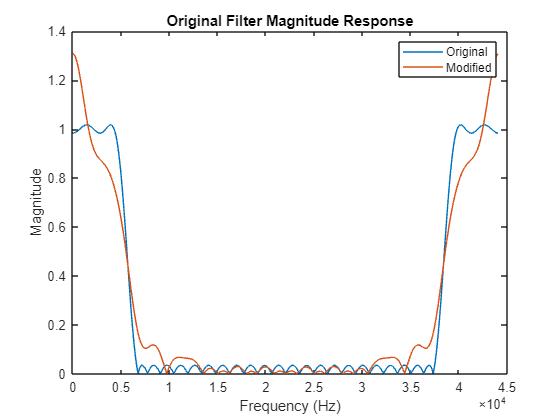

% Assuming c is the original filter coefficients and coefficients is the modified coefficients

% Visualize original filter magnitude response
[H_original, f] = freqz(c, 1, 1024, 'whole', 44100);
plot(f, abs(H_original));
title('Original Filter Magnitude Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
hold on;

% Visualize modified filter magnitude response
[H_modified, ~] = freqz(coefficients, 1, 1024, 'whole', 44100);
plot(f, abs(H_modified));
legend('Original', 'Modified');

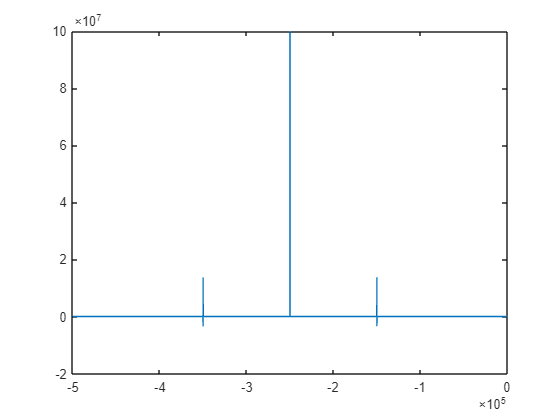

fftx2 = fftshift(fft(x2));
figure;
% Determine frequency axis
N = length(x2); % Length of the signal
df = 500000 / N; % Frequency resolution
freq2 = (-Fs/2) + df*(0:N-1); % Frequency axis centered at 0

plot(freq2, fftx2);

% coefficients = DSD2; 
% coefficients(coefficients < 0) = 0;
% verilog_coefficients = round(coefficients*255);
% disp(verilog_coefficients);
% Convert filter coefficients to 8-bit binary representation

bits = 8; % Number of bits for the binary representation
coeffs_binary = zeros(size(coefficients), 'uint8'); % Initialize array to store binary representations

% Convert each coefficient to binary
for i = 1:numel(coefficients)
    % Scale the coefficient to the range [0, 255] for 8-bit representation
    scaled_coeff = round(coefficients(i) * 255);
    
    % Ensure the scaled coefficient is within the valid range
    scaled_coeff = max(0, min(255, scaled_coeff));
    
    % Convert the scaled coefficient to binary
    coeffs_binary(i) = uint8(scaled_coeff);
end

% Display the binary representation of coefficients
disp('Binary representation of filter coefficients:');

Binary representation of filter coefficients:


disp(coeffs_binary);

    2    0    0    0    1    4    6    3    0    0    0    0    8   29   50   63   63   50   29    8    0    0    0    0    3    6    4    1    0    0    0    2



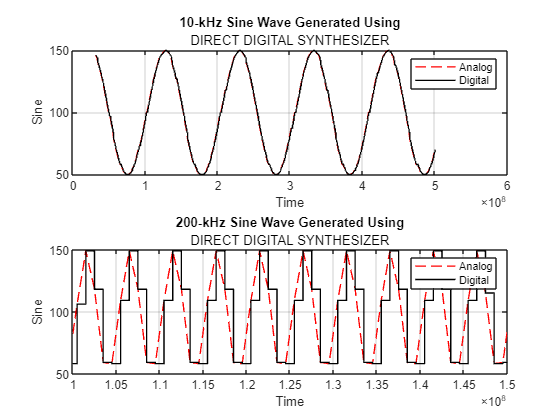

 fileID4 = fopen('Low_FIR_Second.txt', 'r');
 fileID5 = fopen('High_FIR_Second.txt', 'r');
 %data1 = fscanf(fileID, 'Time= %f, Counter= %d, DDS_Sin= %d\n', [3, Inf]);
 data4 = fscanf(fileID4, 'Time = %f, Counter = %d, amp = %d, Data_out = %d\n', [4, Inf]);
 data5 = fscanf(fileID5, 'Time = %f, Counter = %d, amp = %d, Data_out = %d\n', [4, Inf]);
 fclose(fileID4);
 fclose(fileID5);


time4 = data4(1, :);
counter4 = data4(2, :);
amp4 = data4(3, :);
Data_out4 = (data4(4,:)/255); %normalized

time5= data5(1, :);
counter5 = data5(2, :);
amp5 = data5(3, :);
Data_out5 = (data5(4,:)/255); %normalized

% Plot the graphs
figure;
subplot(2, 1, 1);
plot(time4, amp4, '--r', 'LineWidth', 1, 'Color', [1, 0, 0, 0.5]);
hold on;
stairs(time4, amp4, 'k', 'LineWidth', 1);
hold off;
legend('Analog', 'Digital');
xlabel('Time');
ylabel('Sine');
title('10-kHz Sine Wave Generated Using', 'DIRECT DIGITAL SYNTHESIZER');
grid on;

subplot(2, 1, 2);
plot(time5, amp5, '--r', 'LineWidth', 1, 'Color', [1, 0, 0, 0.5]);
hold on;
stairs(time5, amp5, 'k', 'LineWidth', 1);
hold off;
legend('Analog', 'Digital');
xlabel('Time');
ylabel('Sine');
title('200-kHz Sine Wave Generated Using', 'DIRECT DIGITAL SYNTHESIZER');
xlim([100000000  150000000]);
grid on;

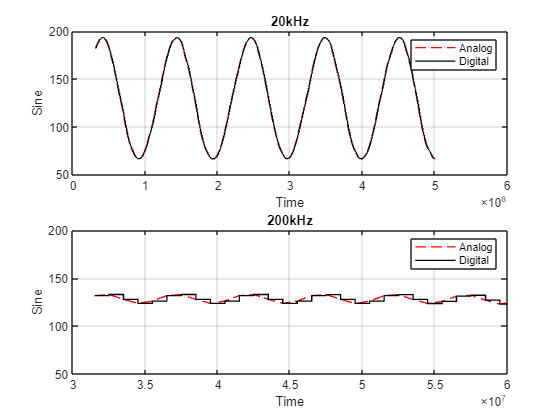



% Plot the graphs
figure;
subplot(2, 1, 1);
plot(time4, Data_out4, '--r', 'LineWidth', 1, 'Color', [1, 0, 0, 0.5]);
hold on;
stairs(time4, Data_out4, 'k', 'LineWidth', 1);
hold off;
legend('Analog', 'Digital');
xlabel('Time');
ylabel('Sine');
title('20kHz');
grid on;

subplot(2, 1, 2);
plot(time5, Data_out5, '--r', 'LineWidth', 1, 'Color', [1, 0, 0, 0.5]);
hold on;
stairs(time5, Data_out5, 'k', 'LineWidth', 1);
hold off;
legend('Analog', 'Digital');
xlabel('Time');
ylabel('Sine');
title('200kHz');
ylim([50 200]);
xlim([30000000 60000000]);
grid on;